# SIM.1. System Response

In MATLAB, create a script in order to plot the expressions for x(t) and y(t). 

Time vector:

dt = 0.5; % sec
time = 0:(dt/100):6*dt; % from 0 to 3 sec

### 1. DC Motor (Step)

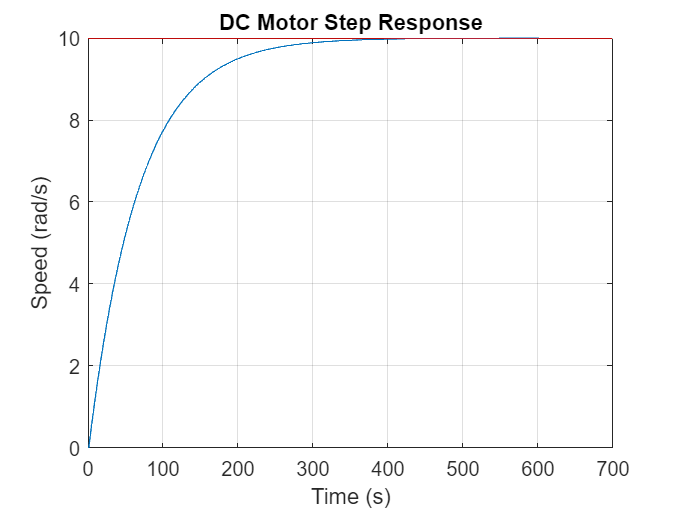

x = 10 - 10*exp(-3*time); % x(t)

% plot
plot(x)
grid
yline(10, 'r')
title("DC Motor Step Response")
xlabel("Time (s)")
ylabel("Speed (rad/s)")

### 2. Automotive Suspension (Step)

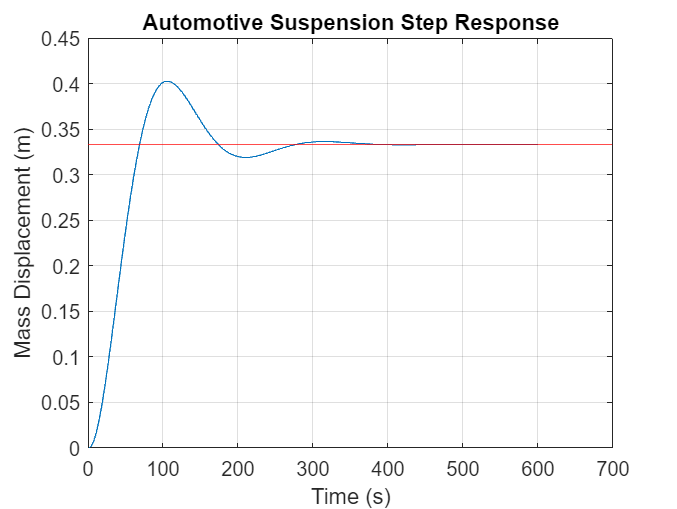

y = 1/3 - (1/3)*sqrt(5/4).*exp(-3*time).*sin(6*time + atan(2)); % y(t)

% plot
plot(y)
grid
yline(1/3, 'r')
title("Automotive Suspension Step Response")
xlabel("Time (s)")
ylabel("Mass Displacement (m)")

### 3. Phugoid Mode (Impulse)

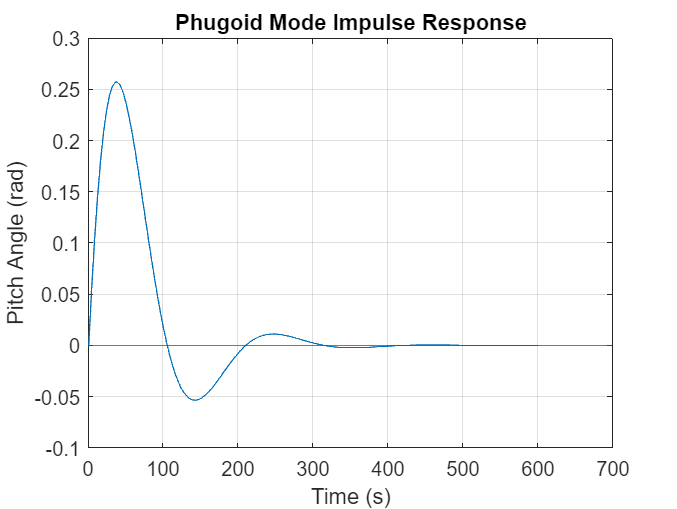

y = (1/2).*exp(-3*time).*sin(6*time); % y(t)

% plot
plot(y)
grid
yline(0, 'r')
title("Phugoid Mode Impulse Response")
xlabel("Time (s)")
ylabel("Pitch Angle (rad)")